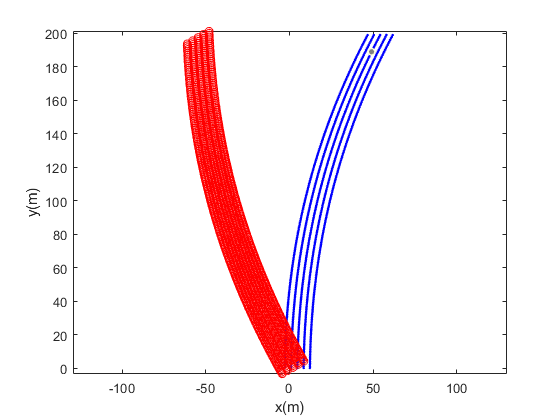

close all;

%% 创建高精度地图中的车道线

LanePoint_R1 = createLanePoint(1e-6, 1e-3, 1e-2 , 1);
LanePoint_R2 = createLanePoint(1e-6, 1e-3, 1e-2 , 4.75);
LanePoint_R3 = createLanePoint(1e-6, 1e-3, 1e-2 , 8.5);
LanePoint_R4 = createLanePoint(1e-6, 1e-3, 1e-2 , 12.25);

LanePoint_L1 = createLanePoint(1e-6, 1e-3, 1e-2 , -2.75);

figure;
plot(LanePoint_L1(:,1),LanePoint_L1(:,2),'.b');
hold on;
plot(LanePoint_R1(:,1),LanePoint_R1(:,2),'.b');
plot(LanePoint_R2(:,1),LanePoint_R2(:,2),'.b');
plot(LanePoint_R3(:,1),LanePoint_R3(:,2),'.b');
plot(LanePoint_R4(:,1),LanePoint_R4(:,2),'.b');
axis equal;
xlabel('x(m)');
ylabel('y(m)');

%% 创建自车的运动轨迹

delta_t = 1;
t = 0:delta_t:100;

time_step = length(t);

x_true_state = zeros(1,time_step);
y_true_state = zeros(1,time_step);
Intercept_true_state = zeros(1,time_step);
x_true_state(1) = 0;
y_true_state(1) = 0;
v_true_state = ones(1,time_step) + 0.01*rand(1,time_step);
theta_true_state = pi/2*(0.9+0.05*rand(1,time_step)).*ones(1,time_step);

for i=2:time_step
    x_true_state(i) = x_true_state(i-1) + v_true_state(i-1)*cos(theta_true_state(i-1))*delta_t;
    y_true_state(i) = y_true_state(i-1) + v_true_state(i-1)*sin(theta_true_state(i-1))*delta_t;
end

% plot(x_true_state,y_true_state,'o-r');


% 找出所有在车左面的点

LanePoints = [LanePoint_L1; LanePoint_R1; LanePoint_R2; LanePoint_R3; LanePoint_R4];

pointAfterTransform = transform_coordinate_system([1,1],pi/6,LanePoints);
plot(pointAfterTransform(:,2), pointAfterTransform(:,1), 'or');